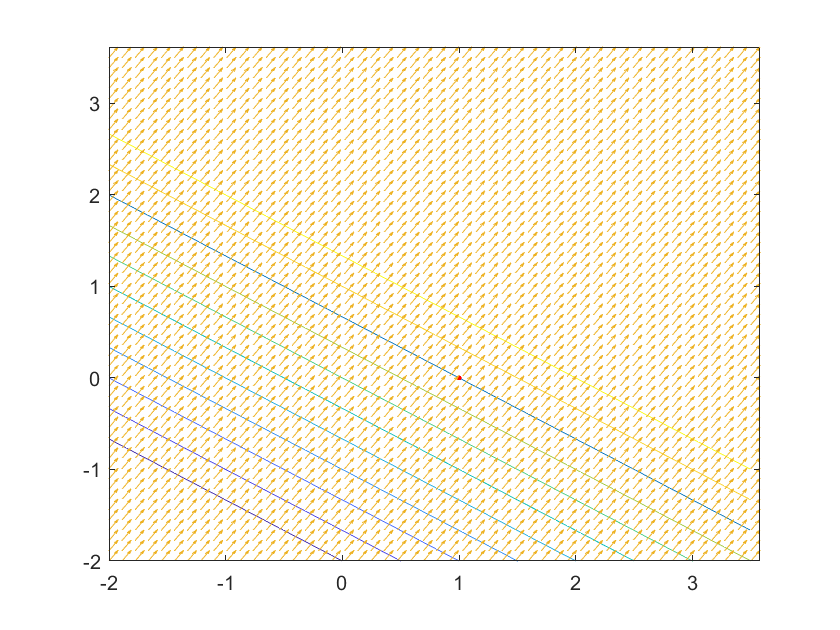

x = linspace(-2, 3.5, 50);
y = linspace(-2, 3.5, 50);
[X,Y] = meshgrid(x,y);
z = @(x,y) 2.*x+3.*y+1;
Z = z(X,Y);
[px,py] = gradient(Z);
figure
[c,h]=contour(X,Y,Z,-5:1:5);
hold on
fimplicit(@(x,y) 2.*x + 3.*y - 2, [-2 3.5 -2 3.5])
plot(1,0,'r.')
hold on
quiver(X,Y,px,py)

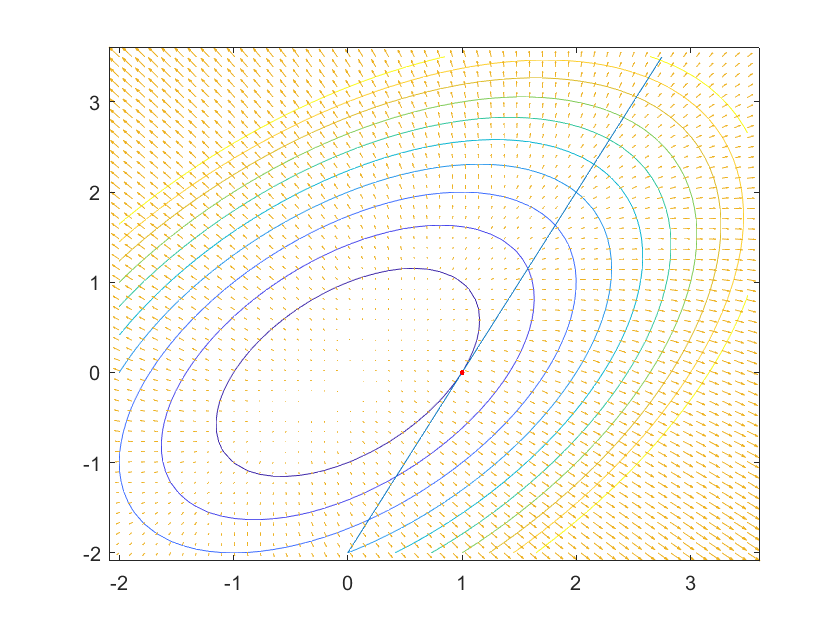


x = linspace(-2, 3.5, 50);
y = linspace(-2, 3.5, 50);
[X,Y] = meshgrid(x,y);
z = @(x,y) x.^2+y.^2-x.*y-5;
Z = z(X,Y);
[px,py] = gradient(Z);
figure
[c,h]=contour(X,Y,Z,-5:1:5);
hold on
fimplicit(@(x,y) 2.*x - y - 2, [-2 3.5 -2 3.5])
plot(1,0,'r.')
hold on
quiver(X,Y,px,py)

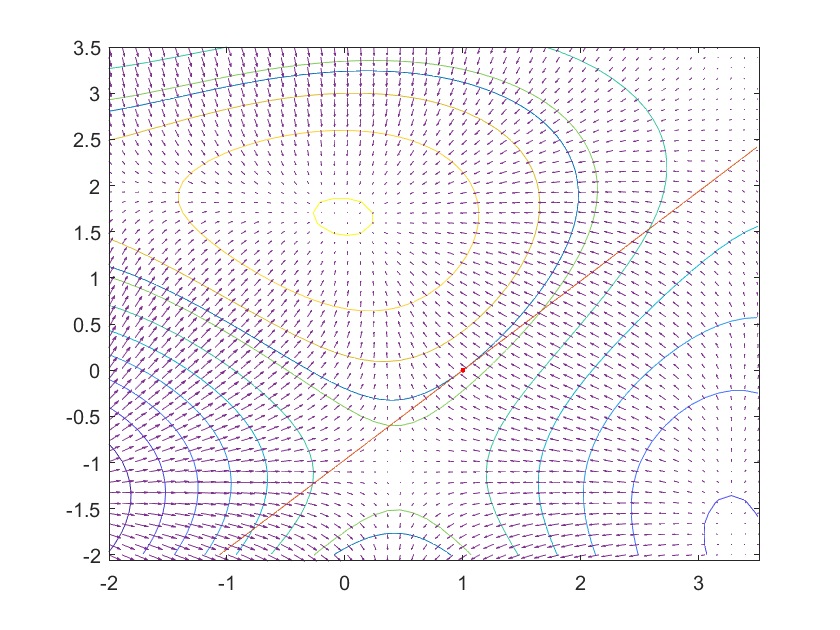


x = linspace(-2, 3.5, 50);
y = linspace(-2, 3.5, 50);
[X,Y] = meshgrid(x,y);
z = @(x,y) (x-5).*cos(y-5) - (y-5).*sin(x-5);
Z = z(X,Y);
[px,py] = gradient(Z);
figure
contour(X,Y,Z);
hold on
fimplicit(@(x,y) (x-5).*cos(y-5) - (y-5).*sin(x-5) + 4.*cos(5) + 5.*sin(4), [-2 3.5 -2 3.5])
fimplicit(@(x,y) (x-1)*(cos(5)+5*cos(4)) + y*(sin(4)-4*sin(5)), [-2 3.5 -2 3.5])
plot(1,0,'r.')
hold on
quiver(X,Y,px,py)

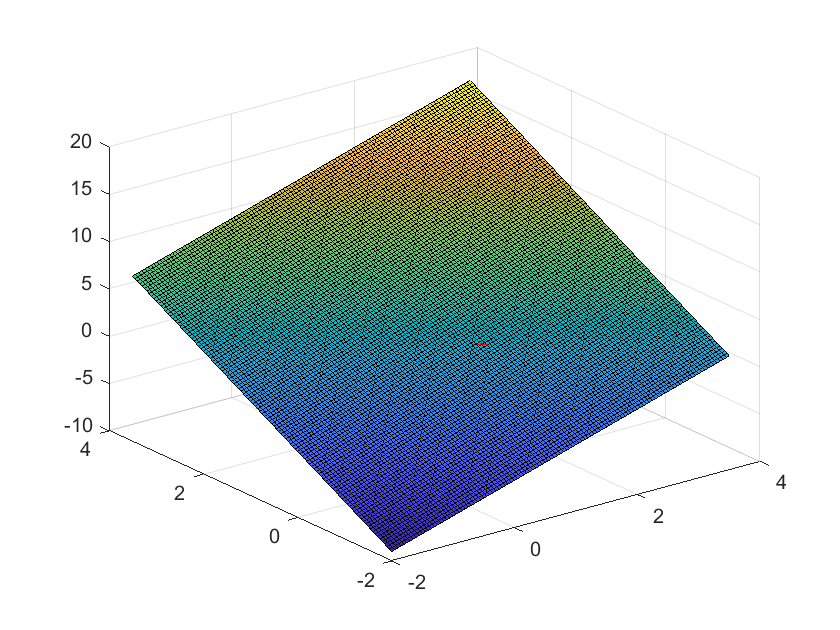

% hold on
% quiver(X,Y,px,py)
% hold on
% yTangentLine = 5 * (x - 1);
% plot(x, yTangentLine, 'b-');

f1 = @(x,y) 2.*x + 3.*y + 1;
figure;
drawtangplane(f1)

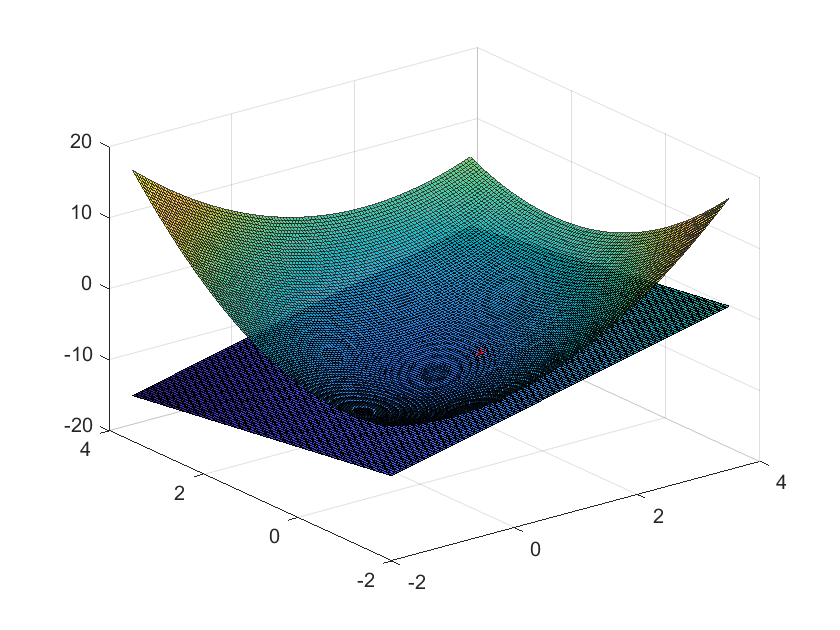


f2 = @(x,y) x.^2 + y.^2 -x.*y - 5;
figure;
drawtangplane(f2)

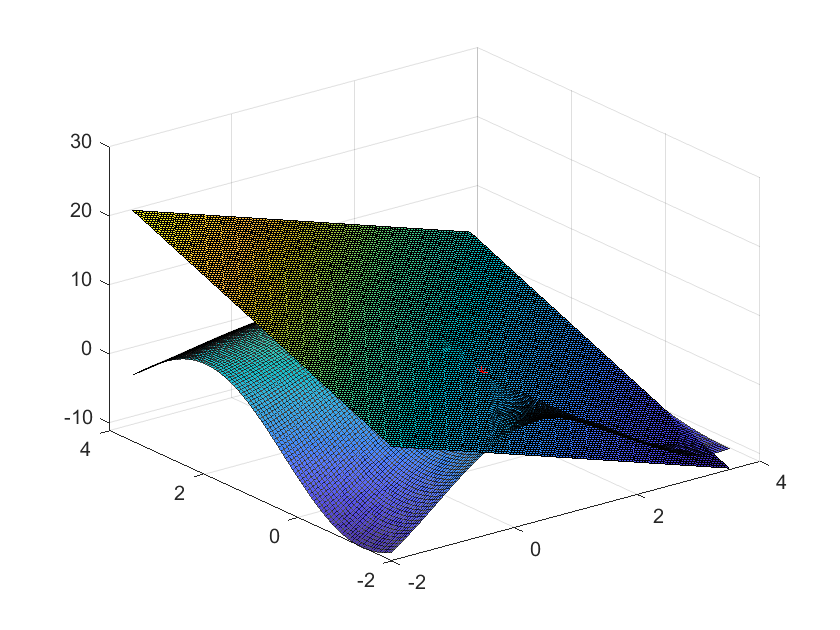


f3 = @(x,y) (x - 5).*cos(y - 5) - (y - 5).* sin(x - 5);
figure;
drawtangplane(f3)

function drawtangplane(f)
    [xx,yy] = meshgrid(-2:0.05:3.5);
    [fx,fy] = gradient(f(xx,yy),0.05);
    x0 = 1;
    y0 = 0;
    t = (xx == x0) & (yy == y0);
    indt = find(t);
    fx0 = fx(indt);
    fy0 = fy(indt);
    z = @(x,y) f(x0,y0) + fx0*(x-x0) + fy0*(y-y0);
    surf(xx,yy,f(xx,yy),'EdgeAlpha',0.7,'FaceAlpha',0.9)
    hold on
    surf(xx,yy,z(xx,yy))
    plot3(x0,y0,f(x0,y0),'r*')
end